# `Exercise 1)`

# `Task A)`

clear;
% given data
u=[1 2 3 4 5]';
y=[6 7 8 9 -1]';

% you can test the following calls. After the call the correct answer is
% given

uy2phi([y u],[1 1 0])

ans =      7     6     2
     8     7     3
     9     8     4
    -1     9     5


%      7     6     2
%      8     7     3
%      9     8     4
%     -1     9     5

uy2phi([y u],[1 1 1])

ans =      7     6     1
     8     7     2
     9     8     3
    -1     9     4


%      7     6     1
%      8     7     2
%      9     8     3
%     -1     9     4

uy2phi([y u],[1 1 2])

ans =      8     7     1
     9     8     2
    -1     9     3


%      8     7     1
%      9     8     2
%     -1     9     3

uy2phi([y u],[1 2 2])

ans =      9     8     2     1
    -1     9     3     2


%      9     8     2     1
%     -1     9     3     2

uy2phi([y u],[3 2 2])

ans =      9     8     7     6     2     1
    -1     9     8     7     3     2


%      9     8     7     6     2     1
%     -1     9     8     7     3     2

# `Task C)`

clear;
% given data
u=[1 -1 2 -1 3 0 1]';
y=[2 -2 -3 -4 -2 0 1]';

% Your estimate should be
model=arxfit([y u],[2 1 2]);

model.theta

ans =     1.1573
   -0.5004
    0.2366



%     1.1573
%    -0.5004
%     0.2366


idpredict(model,[y u],1)

ans =          0
    2.3146
   -3.0789
   -2.7077
   -2.6550
   -0.5496
    1.7105



%          0
%     2.3146
%    -3.0789
%    -2.7077
%    -2.6550
%    -0.5496
%     1.7105


idpredict(model,[y u],3)

ans =          0
         0
    0.2366
    3.1374
   -6.7238
    0.9484
   -0.9916



%          0
%          0
%     0.2366
%     0.8209
%    -1.2256
%    -0.2234
%     0.5249


ysim=idsimulate(model,u)

ysim =          0
         0
    0.2366
    0.0372
    0.3978
    0.2052
    0.7481



%          0
%          0
%     0.2366
%     0.0372
%     0.3978
%     0.2052
%     0.7481

# `Task D)`

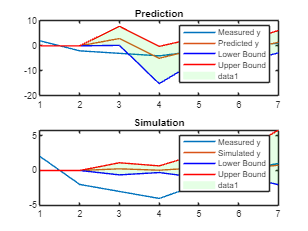

% The following two calls give the figures displayed in the project
% instructions

idcompare(model,[y u],2)

idcompare(model,[y u],Inf)

Out of memory. The likely cause is an infinite recursion within the program.

Error in idpredict (line 4)
        phi = uy2phi([zeros(zero, 2); z], [model.na, model.nb, model.nk]); % Generate regressor

# `Exercise 2)`


Parameter Set 1, N = 10, Noise Variance = 0.01:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


   -1.5021
    3.6458



Estimated B coefficients from ARX model:


    5.0752
    0.2294



MSE for OE Model: 22.0553      7.22097


MSE for ARX Model: 11.3822      11.4038


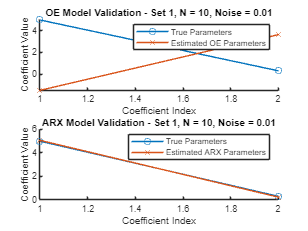


Parameter Set 1, N = 10, Noise Variance = 0.10:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    0.7500
    1.9977



Estimated B coefficients from ARX model:


    5.3579
   -0.7643



MSE for OE Model: 13.5382      1.54238


MSE for ARX Model: 16.6778      13.3578


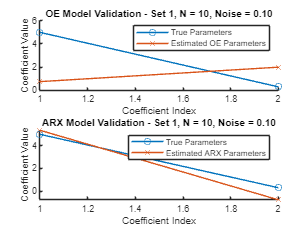


Parameter Set 1, N = 10, Noise Variance = 1.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    0.3635
   -1.7410



Estimated B coefficients from ARX model:


    4.6769
    3.2332



MSE for OE Model: 33.4695      2.08492


MSE for ARX Model: 1.61304      13.8803


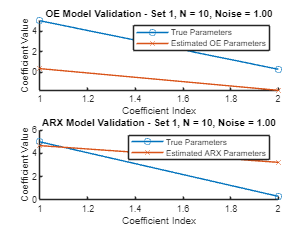


Parameter Set 1, N = 10, Noise Variance = 5.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    0.4255
    1.8497



Estimated B coefficients from ARX model:


    6.2750
    1.5553



MSE for OE Model: 15.4249      1.20874


MSE for ARX Model: 6.74579      18.6383


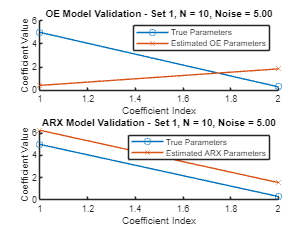


Parameter Set 1, N = 100, Noise Variance = 0.01:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.2094
   -0.3683



Estimated B coefficients from ARX model:


    4.9723
    0.2565



MSE for OE Model: 21.5936     0.636842


MSE for ARX Model: 11.2507      10.9159


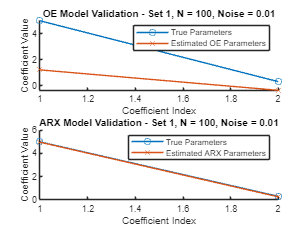


Parameter Set 1, N = 100, Noise Variance = 0.10:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.2060
   -0.3658



Estimated B coefficients from ARX model:


    5.0074
    0.4852



MSE for OE Model: 21.5931     0.632062


MSE for ARX Model: 10.1919      11.0969


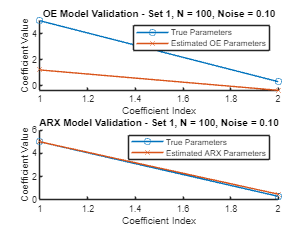


Parameter Set 1, N = 100, Noise Variance = 1.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.2509
   -0.4014



Estimated B coefficients from ARX model:


    5.1420
    0.9734



MSE for OE Model: 21.6152     0.698087


MSE for ARX Model: 8.11674      11.9492


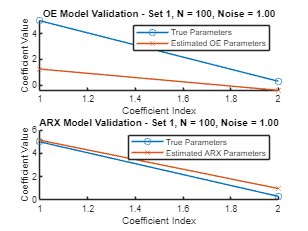


Parameter Set 1, N = 100, Noise Variance = 5.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.0216
   -0.2012



Estimated B coefficients from ARX model:


    5.0731
    3.0775



MSE for OE Model: 21.4396     0.385964


MSE for ARX Model: 1.85067      15.2483


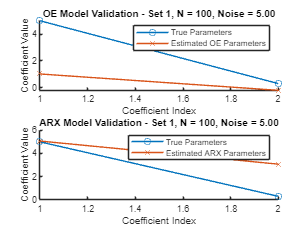


Parameter Set 1, N = 1000, Noise Variance = 0.01:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.1987
   -0.3589



Estimated B coefficients from ARX model:


    4.9969
    0.3293



MSE for OE Model: 21.5838     0.620862


MSE for ARX Model: 10.9076      11.0308


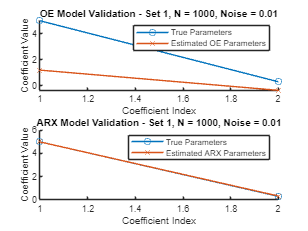


Parameter Set 1, N = 1000, Noise Variance = 0.10:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.2031
   -0.3623



Estimated B coefficients from ARX model:


    4.9990
    0.4323



MSE for OE Model: 21.5854     0.627099


MSE for ARX Model: 10.4321       11.049


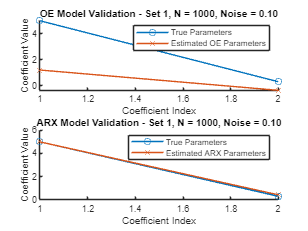


Parameter Set 1, N = 1000, Noise Variance = 1.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.1994
   -0.3585



Estimated B coefficients from ARX model:


    5.0839
    1.4529



MSE for OE Model: 21.5794     0.621248


MSE for ARX Model: 6.29447      12.1075


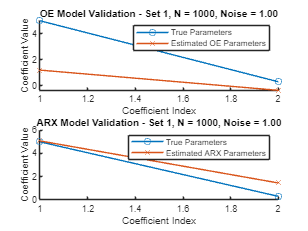


Parameter Set 1, N = 1000, Noise Variance = 5.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.1675
   -0.3346



Estimated B coefficients from ARX model:


    4.9443
    3.0841



MSE for OE Model: 21.5729      0.57763


MSE for ARX Model: 1.83697      14.6602


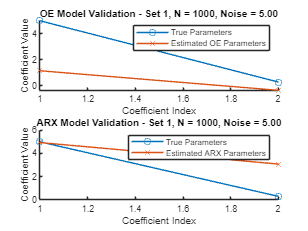


Parameter Set 1, N = 5000, Noise Variance = 0.01:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.2020
   -0.3617



Estimated B coefficients from ARX model:


    5.0009
    0.3016



MSE for OE Model: 21.5863      0.62567


MSE for ARX Model: 11.0373      11.0495


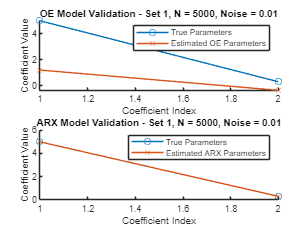


Parameter Set 1, N = 5000, Noise Variance = 0.10:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.1981
   -0.3582



Estimated B coefficients from ARX model:


    5.0058
    0.4531



MSE for OE Model: 21.5825      0.61992


MSE for ARX Model: 10.3374      11.0842


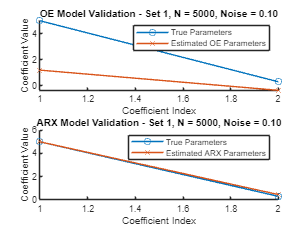


Parameter Set 1, N = 5000, Noise Variance = 1.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.2020
   -0.3619



Estimated B coefficients from ARX model:


    5.0115
    1.3946



MSE for OE Model: 21.5874     0.625815


MSE for ARX Model: 6.49943      11.6983


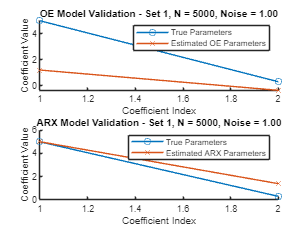


Parameter Set 1, N = 5000, Noise Variance = 5.00:


True B coefficients:


    5.0000    0.3000



Estimated B coefficients from OE model:


    1.2154
   -0.3741



Estimated B coefficients from ARX model:


    5.0091
    2.9892



MSE for OE Model: 21.602     0.646131


MSE for ARX Model: 2.0217      14.7039


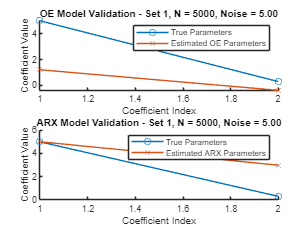


Parameter Set 2, N = 10, Noise Variance = 0.01:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


   -1.4894
   -0.1132



Estimated B coefficients from ARX model:


    0.6436
    0.1164



MSE for OE Model: 2.7275      0.8351


MSE for ARX Model: 0.17191     0.40585


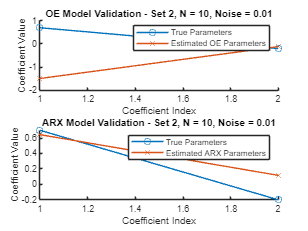


Parameter Set 2, N = 10, Noise Variance = 0.10:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


   -0.2866
   -0.2031



Estimated B coefficients from ARX model:


    0.5919
    0.3766



MSE for OE Model: 0.89452   0.0037578


MSE for ARX Model: 0.058131     0.47978


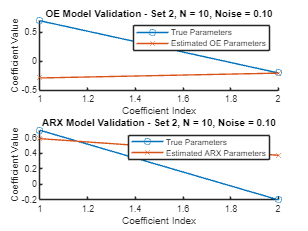


Parameter Set 2, N = 10, Noise Variance = 1.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


   -1.9178
    1.1895



Estimated B coefficients from ARX model:


    1.0397
    0.5861



MSE for OE Model: 3.5462      2.4407


MSE for ARX Model: 0.064191      1.0775


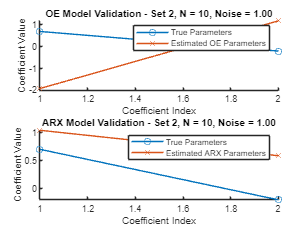


Parameter Set 2, N = 10, Noise Variance = 5.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


   1.0e+03 *

   -0.0155
    1.0240



Estimated B coefficients from ARX model:


   -0.1868
    0.6970



MSE for OE Model: 523704.9951      524612.1559


MSE for ARX Model: 0.39322     0.40241


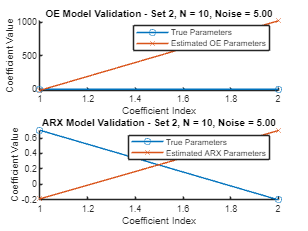


Parameter Set 2, N = 100, Noise Variance = 0.01:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.7668
   -0.4601



Estimated B coefficients from ARX model:


    0.7092
   -0.1089



MSE for OE Model: 0.67519     0.50123


MSE for ARX Model: 0.32722     0.41744


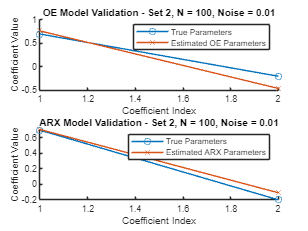


Parameter Set 2, N = 100, Noise Variance = 0.10:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.7182
   -0.4367



Estimated B coefficients from ARX model:


    0.6353
    0.2022



MSE for OE Model: 0.6462     0.44959


MSE for ARX Model: 0.12598     0.42972


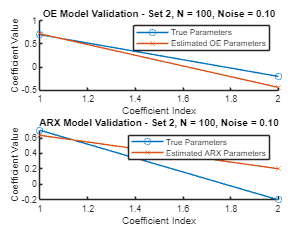


Parameter Set 2, N = 100, Noise Variance = 1.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.4575
   -0.2825



Estimated B coefficients from ARX model:


    0.6620
    0.3073



MSE for OE Model: 0.51209     0.21954


MSE for ARX Model: 0.077828     0.50021


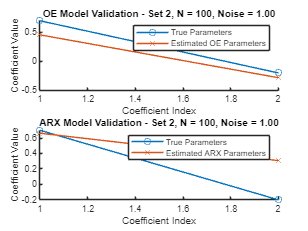


Parameter Set 2, N = 100, Noise Variance = 5.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.0970
   -0.3040



Estimated B coefficients from ARX model:


    0.8467
    0.4426



MSE for OE Model: 0.68583    0.049517


MSE for ARX Model: 0.043897      0.7542


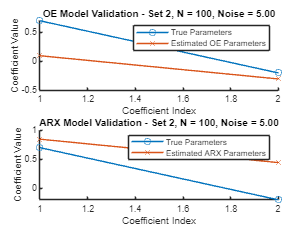


Parameter Set 2, N = 1000, Noise Variance = 0.01:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.8116
   -0.4822



Estimated B coefficients from ARX model:


    0.7028
   -0.1460



MSE for OE Model: 0.70499     0.55149


MSE for ARX Model: 0.35782     0.40895


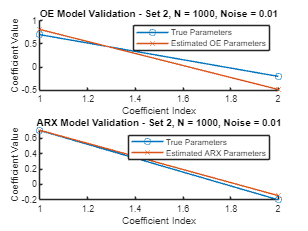


Parameter Set 2, N = 1000, Noise Variance = 0.10:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.7080
   -0.4393



Estimated B coefficients from ARX model:


    0.7014
    0.1971



MSE for OE Model: 0.64898     0.44081


MSE for ARX Model: 0.12644     0.48513


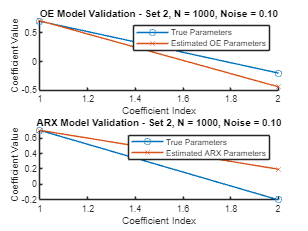


Parameter Set 2, N = 1000, Noise Variance = 1.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.8078
   -0.4499



Estimated B coefficients from ARX model:


    0.7533
    0.3079



MSE for OE Model: 0.66693     0.53903


MSE for ARX Model: 0.078276     0.58342


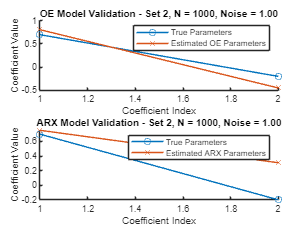


Parameter Set 2, N = 1000, Noise Variance = 5.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.5125
   -0.3325



Estimated B coefficients from ARX model:


    0.7917
    0.3271



MSE for OE Model: 0.55064     0.26263


MSE for ARX Model: 0.073742     0.63069


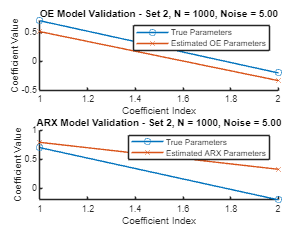


Parameter Set 2, N = 5000, Noise Variance = 0.01:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.8040
   -0.4805



Estimated B coefficients from ARX model:


    0.7006
   -0.1357



MSE for OE Model: 0.70225     0.54338


MSE for ARX Model: 0.34922     0.40757


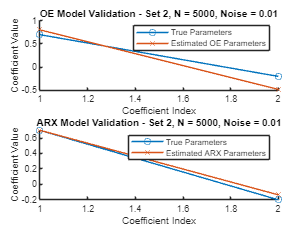


Parameter Set 2, N = 5000, Noise Variance = 0.10:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.7886
   -0.4794



Estimated B coefficients from ARX model:


    0.6980
    0.1511



MSE for OE Model: 0.69946     0.52775


MSE for ARX Model: 0.15065     0.46486


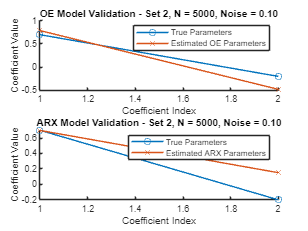


Parameter Set 2, N = 5000, Noise Variance = 1.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.8171
   -0.4800



Estimated B coefficients from ARX model:


    0.7150
    0.3045



MSE for OE Model: 0.70302     0.55639


MSE for ARX Model: 0.078316     0.54592


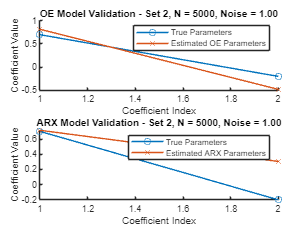


Parameter Set 2, N = 5000, Noise Variance = 5.00:


True B coefficients:


    0.7000   -0.2000



Estimated B coefficients from OE model:


    0.7914
   -0.4395



Estimated B coefficients from ARX model:


    0.7458
    0.3385



MSE for OE Model: 0.65343      0.5201


MSE for ARX Model: 0.066401     0.59229


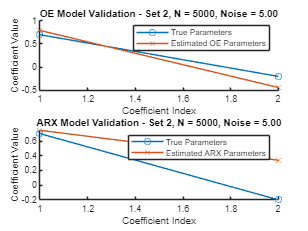


Parameter Set 3, N = 10, Noise Variance = 0.01:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.6739
   -1.8958



Estimated B coefficients from ARX model:


    0.2111
    0.0510



MSE for OE Model: 2.291      2.5779


MSE for ARX Model: 0.0073682    0.011165


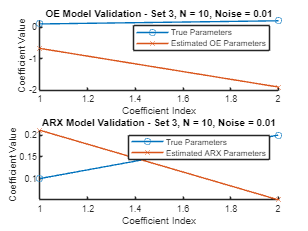


Parameter Set 3, N = 10, Noise Variance = 0.10:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.3404
    1.0354



Estimated B coefficients from ARX model:


    0.1198
    0.0918



MSE for OE Model: 0.53442     0.49492


MSE for ARX Model: 0.00022911   0.0090709


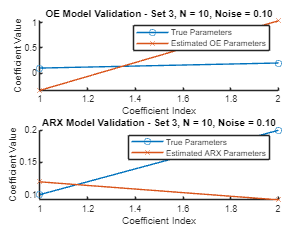


Parameter Set 3, N = 10, Noise Variance = 1.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -2.4426
   -0.6289



Estimated B coefficients from ARX model:


   -0.3061
   -0.1574



MSE for OE Model: 3.4981      3.8353


MSE for ARX Model: 0.1156     0.19195


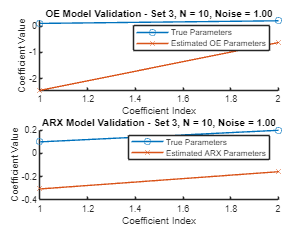


Parameter Set 3, N = 10, Noise Variance = 5.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.1065
   -3.6971



Estimated B coefficients from ARX model:


    5.3486
   -5.9047



MSE for OE Model: 7.2303      7.6407


MSE for ARX Model: 31.802      31.8876


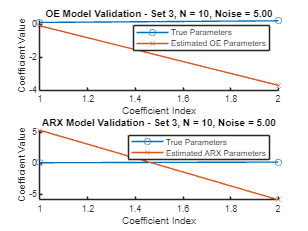


Parameter Set 3, N = 100, Noise Variance = 0.01:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.7176
    0.2792



Estimated B coefficients from ARX model:


    0.0778
    0.1765



MSE for OE Model: 0.35031     0.42415


MSE for ARX Model: 0.0031769   0.0077457


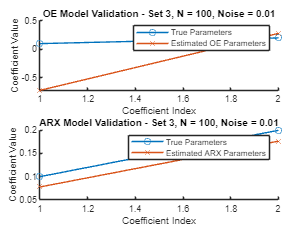


Parameter Set 3, N = 100, Noise Variance = 0.10:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.6381
    0.2399



Estimated B coefficients from ARX model:


    0.0777
    0.1862



MSE for OE Model: 0.28217     0.35199


MSE for ARX Model: 0.0039675   0.0075783


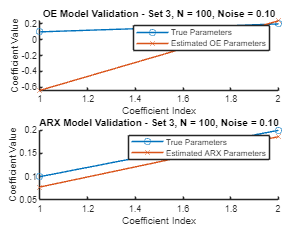


Parameter Set 3, N = 100, Noise Variance = 1.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.0155
    0.1618



Estimated B coefficients from ARX model:


    0.1864
    0.3955



MSE for OE Model: 0.0085751    0.023946


MSE for ARX Model: 0.047398    0.019208


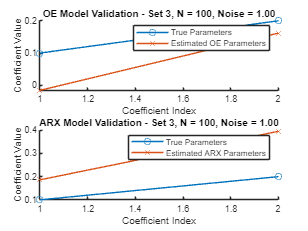


Parameter Set 3, N = 100, Noise Variance = 5.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


    0.0302
   -0.0111



Estimated B coefficients from ARX model:


    0.5536
    0.2547



MSE for OE Model: 0.00861    0.036701


MSE for ARX Model: 0.11486    0.064029


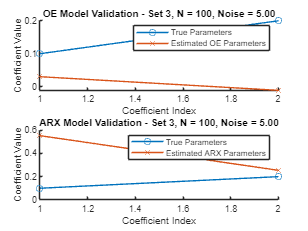


Parameter Set 3, N = 1000, Noise Variance = 0.01:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.7145
    0.2844



Estimated B coefficients from ARX model:


    0.1030
    0.2049



MSE for OE Model: 0.34873     0.42173


MSE for ARX Model: 0.0055057   0.0047193


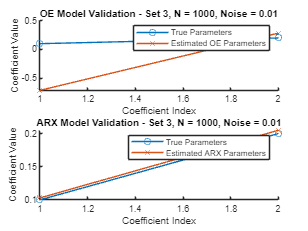


Parameter Set 3, N = 1000, Noise Variance = 0.10:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.6917
    0.3064



Estimated B coefficients from ARX model:


    0.0685
    0.1823



MSE for OE Model: 0.33465     0.40318


MSE for ARX Model: 0.0038802   0.0088095


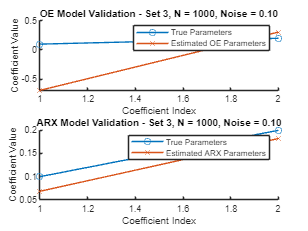


Parameter Set 3, N = 1000, Noise Variance = 1.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.3508
    0.6274



Estimated B coefficients from ARX model:


    0.0609
    0.1422



MSE for OE Model: 0.24072     0.24306


MSE for ARX Model: 0.0016523    0.011339


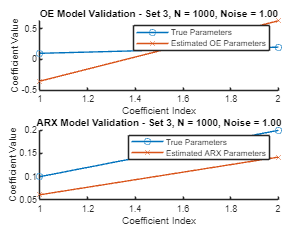


Parameter Set 3, N = 1000, Noise Variance = 5.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.2466
    0.4478



Estimated B coefficients from ARX model:


    0.2136
    0.0346



MSE for OE Model: 0.12054     0.13042


MSE for ARX Model: 0.0085928    0.013769


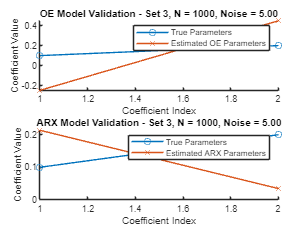


Parameter Set 3, N = 5000, Noise Variance = 0.01:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.7003
    0.2997



Estimated B coefficients from ARX model:


    0.0980
    0.1934



MSE for OE Model: 0.34019     0.41025


MSE for ARX Model: 0.0043615   0.0052263


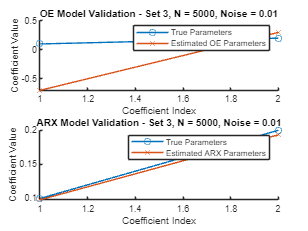


Parameter Set 3, N = 5000, Noise Variance = 0.10:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.7073
    0.2923



Estimated B coefficients from ARX model:


    0.1027
    0.1821



MSE for OE Model: 0.34439     0.41589


MSE for ARX Model: 0.0033756   0.0048909


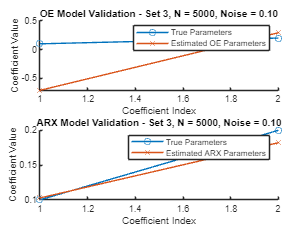


Parameter Set 3, N = 5000, Noise Variance = 1.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.6717
    0.3223



Estimated B coefficients from ARX model:


    0.1107
    0.1535



MSE for OE Model: 0.32248     0.38742


MSE for ARX Model: 0.0014859   0.0050688


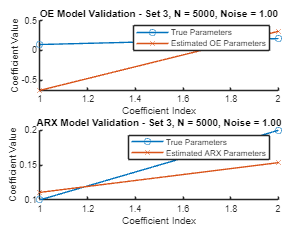


Parameter Set 3, N = 5000, Noise Variance = 5.00:


True B coefficients:


    0.1000    0.2000



Estimated B coefficients from OE model:


   -0.5557
    0.4320



Estimated B coefficients from ARX model:


    0.1328
    0.2139



MSE for OE Model: 0.27007     0.31243


MSE for ARX Model: 0.0070301   0.0023521


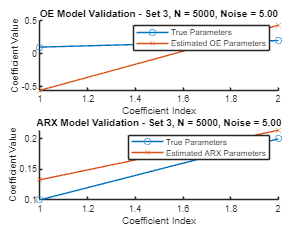

clear;
% multiple sets of true system parameters
param_sets = {
    struct('B_true', [5, 0.3], 'A_true', [1, -1.2, 0.36]),
    struct('B_true', [0.7, -0.2], 'A_true', [1, -0.8, 0.48]),
    struct('B_true', [0.1, 0.2], 'A_true', [1, 0.7, -0.3])
};

% sets of data points and noise variances
Ns = [10, 100, 1000, 5000];
noise_variances = [0.01, 0.1, 1, 5];

% Loop over each parameter set
for i = 1:length(param_sets)
    B_true = param_sets{i}.B_true;
    A_true = param_sets{i}.A_true;
    nk = 1; % constant delay for simplicity
    
    % Loop over different data point sizes and noise variances
    for N = Ns
        for noise_variance = noise_variances
            % input data
            u = randn(N, 1);

            % noise-free system output using the current true parameters
            y_true = filter([0, B_true], A_true, u);

            % white noise to the output
            noise = sqrt(noise_variance) * randn(N, 1);
            y_noisy = y_true + noise;

            % Fitting models
            nb = length(B_true);  % Number of B coefficients
            nf = length(A_true) - 1;  % Number of F coefficients in OE model

            oe_model = oefit([y_noisy, u], [nb, nf, nk]);
            arx_model = arxfit([y_noisy, u], [nf, nb, nk]);

            % results
            fprintf('\nParameter Set %d, N = %d, Noise Variance = %.2f:\n', i, N, noise_variance);
            disp('True B coefficients:');
            disp(B_true);
            disp('Estimated B coefficients from OE model:');
            disp(oe_model.B);
            disp('Estimated B coefficients from ARX model:');
            disp(arx_model.B);

            mse_oe = mean((B_true - oe_model.B).^2);
            mse_arx = mean((B_true - arx_model.B).^2);
            disp(['MSE for OE Model: ', num2str(mse_oe)]);
            disp(['MSE for ARX Model: ', num2str(mse_arx)]);

            % Plotting
            figure;
            subplot(2,1,1);
            hold on;
            plot(B_true, 'o-', 'DisplayName', 'True Parameters');
            plot(oe_model.B, 'x-', 'DisplayName', 'Estimated OE Parameters');
            title(sprintf('OE Model Validation - Set %d, N = %d, Noise = %.2f', i, N, noise_variance));
            legend;
            xlabel('Coefficient Index');
            ylabel('Coefficient Value');
            hold off;

            subplot(2,1,2);
            hold on;
            plot(B_true, 'o-', 'DisplayName', 'True Parameters');
            plot(arx_model.B, 'x-', 'DisplayName', 'Estimated ARX Parameters');
            title(sprintf('ARX Model Validation - Set %d, N = %d, Noise = %.2f', i, N, noise_variance));
            legend;
            xlabel('Coefficient Index');
            ylabel('Coefficient Value');
            hold off;
        end
    end
end

# `Exercise 3)`

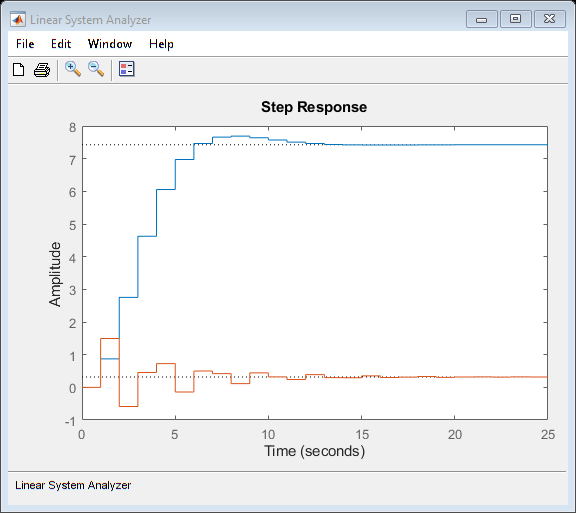

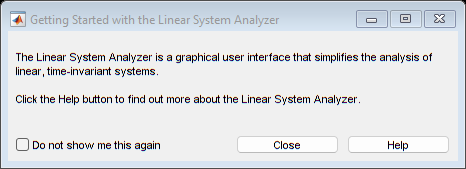

clear;
load('exercise1.mat');  
load('exercise2.mat');

z = [y, u]; 

% several combinations of na, nb, nk for ARX models
arx_model_1 = arxfit(z, [2, 2, 1]);  % Example: na = 2, nb = 2, nk = 1
arx_model_2 = arxfit(z, [3, 3, 1]);  % Increasing complexity

arx_model_1_tf = id2tf(arx_model_1);
arx_model_2_tf = id2tf(arx_model_2);

% OE models with different nf and nb
oe_model_1 = oefit(z, [2, 2, 1]);    % nf = 2, nb = 2, nk = 1
oe_model_2 = oefit(z, [3, 3, 1]);    % Increasing complexity

oe_model_1_tf = id2tf(oe_model_1);
oe_model_2_tf = id2tf(oe_model_2);


ltiview('step', arx_model_1_tf, oe_model_1_tf);

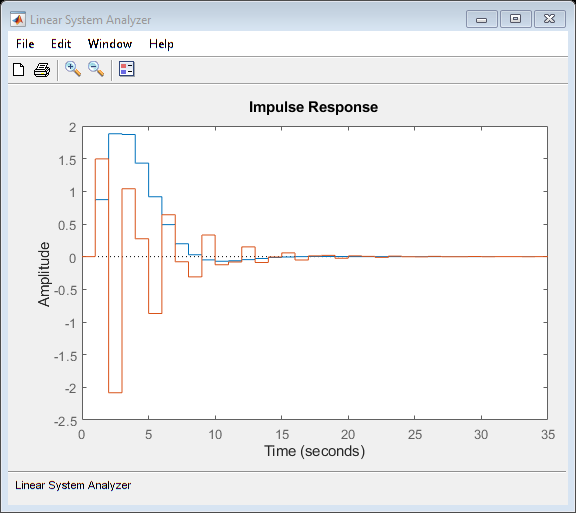

ltiview('impulse', arx_model_1_tf, oe_model_1_tf);

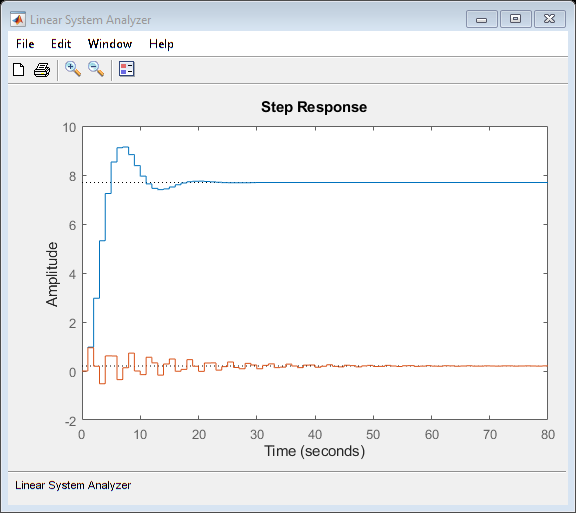


ltiview('step', arx_model_2_tf, oe_model_2_tf);

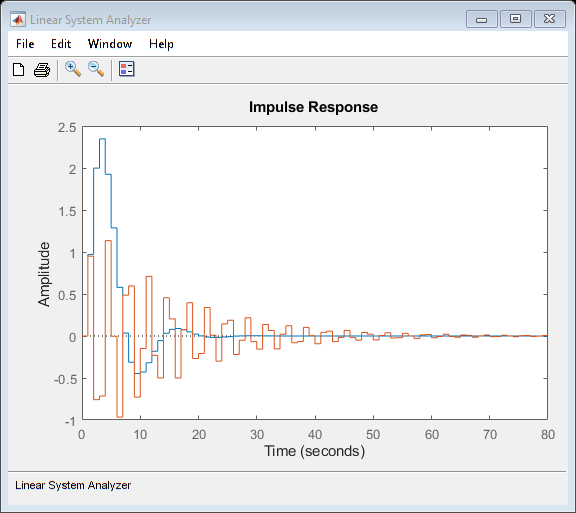

ltiview('impulse', arx_model_2_tf, oe_model_2_tf);

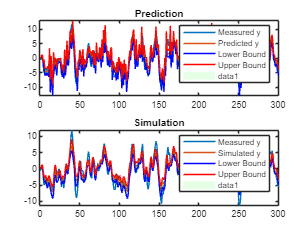


idcompare(arx_model_1, z, 3);  

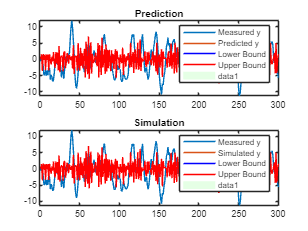

idcompare(oe_model_1, z, 3);


arx_model_z1 = arxfit(z1, [2, 2, 1]);
oe_model_z1 = oefit(z1, [2, 2, 1]);

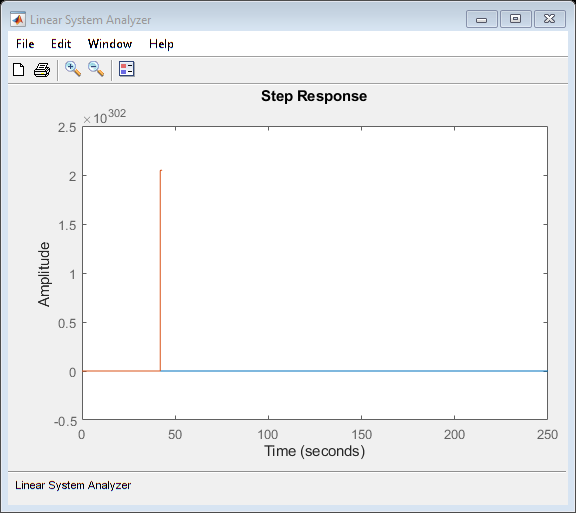


arx_model_z1_tf = id2tf(arx_model_z1);
oe_model_z1_tf = id2tf(oe_model_z1);

ltiview('step', arx_model_z1_tf, oe_model_z1_tf);

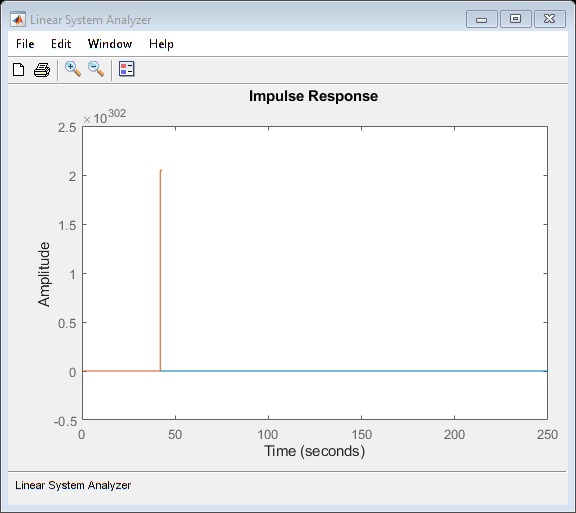

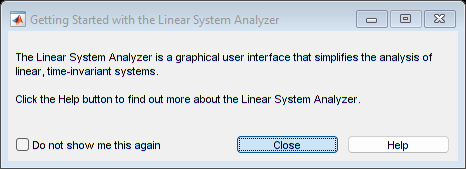

ltiview('impulse', arx_model_z1_tf, oe_model_z1_tf);

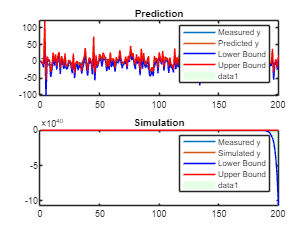


idcompare(arx_model_z1, z2, 3);

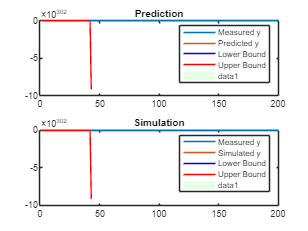

idcompare(oe_model_z1, z2, 3);